# Age-related differences in upper limb proprioceptive acuity

Adamo et al. (2007)

Duncan Tulimieri - July 11, 2022

clear; clc;
cd('/Users/duncan/Documents/GitHub/Recreate-Papers/Adamo07')

## Data

### Table 1

#### Younger Adults

t1_YA(:,:,1) = [1.58 1.1; ...
                3.27 1.5; ...
                3.97 1.7];
t1_YA(:,:,2) = [2.20 1.6; ...
                4.54 2.3; ...
                5.95 2.5];
t1_YA(:,:,3) = [2.88 1.7; ...
                5.34 1.0; ...
                6.38 3.3]; 

#### Older Adults

t1_OA(:,:,1) = [3.30 1.6; ...
                4.65 2.4; ...
                5.47 3.6];
t1_OA(:,:,2) = [3.80 1.7; ...
                5.10 2.3; ...
                6.60 3.6];
t1_OA(:,:,3) = [4.60 3.2; ...
               6.50 3.5; ...
               9.84 4.1]; 

### Table 2

#### Younger Adults

t2_YA(:,:,1) = [1.15 0.48; ...
                2.06 0.58; ...
                2.73 0.24];
t2_YA(:,:,2) = [1.66 0.60; ...
                2.54 0.78; ...
                3.04 0.28];
t2_YA(:,:,3) = [2.2 1.10; ...
                3.2 0.68; ...
                3.4 0.64]; 

#### Older Adults

t2_OA(:,:,1) = [2.1 0.94; ...
                2.7 1.30; ...
                2.8 1.00];
t2_OA(:,:,2) = [3.46 1.76; ...
                3.04 1.38; ...
                3.70 1.48];
t2_OA(:,:,3) = [2.52 1.52; ...
                3.24 0.74; ...
                3.68 1.80]; 

## Table 1

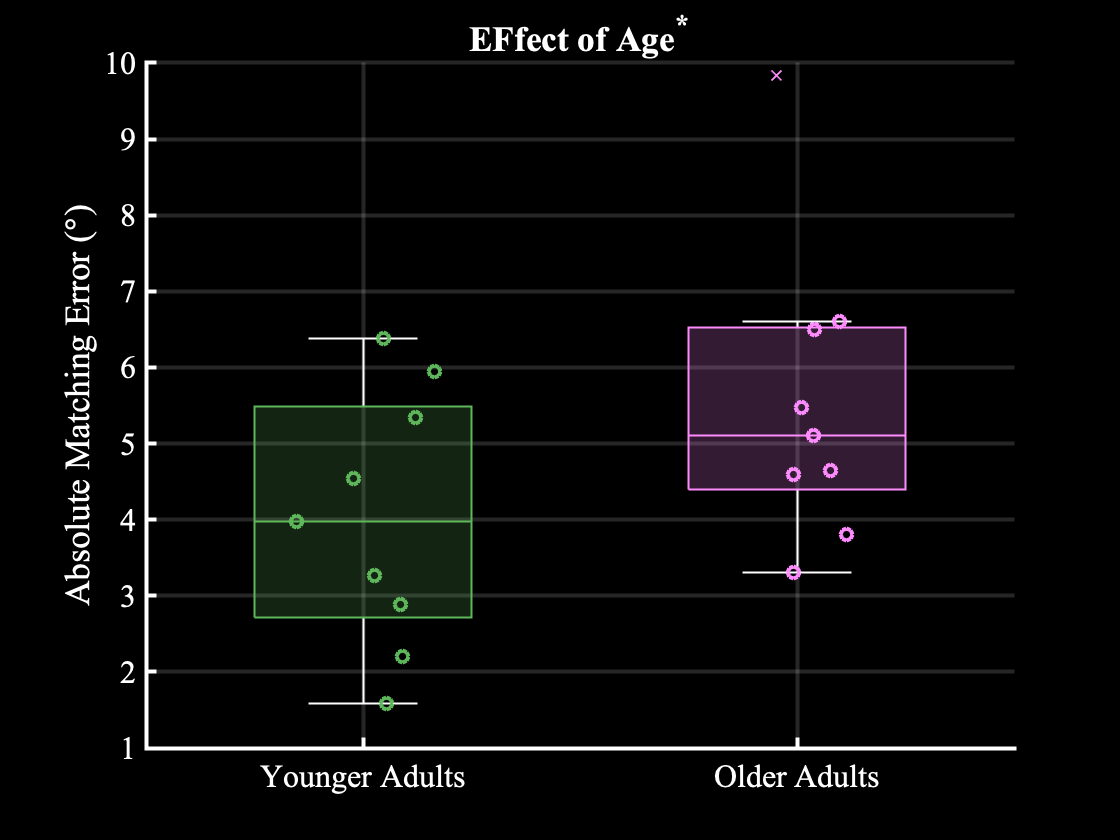

t1 = VisualizeAdamoTable(t1_YA, t1_OA, 'Absolute Matching Error (\circ)', 1);
% significance
set(t1, 'effectOfAge', true); set(t1, 'btwAge', 1);
set(t1, 'effectOfCondition', [true true false])
set(t1, 'effectOfDisplacement', [true true true]);
set(t1, 'btwDisplacements', [0.001 1 0.001]); set(t1, 'winDisplacements', [1 1 1]);
set(t1, 'btwConditions', [1 0.002 0.001]); set(t1, 'winConditions', [1 1 1]);
t1.effectsOfAge(); 

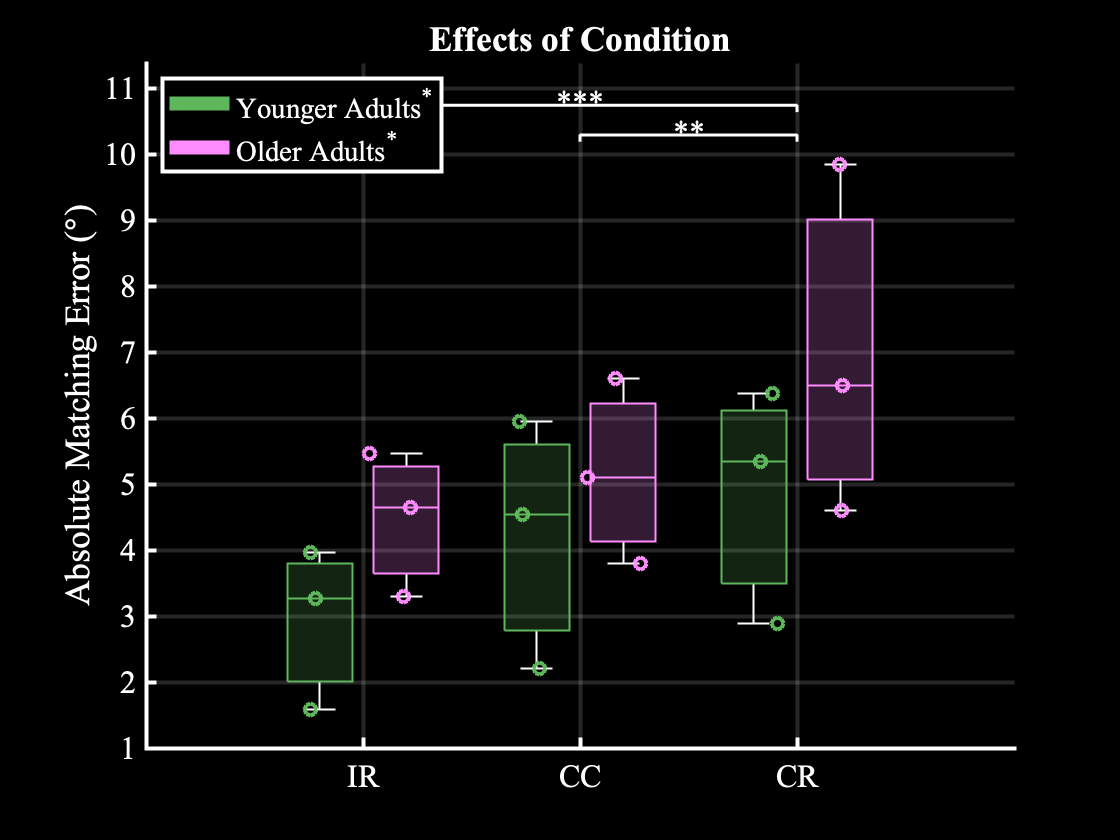

t1.effectsOfConditions();

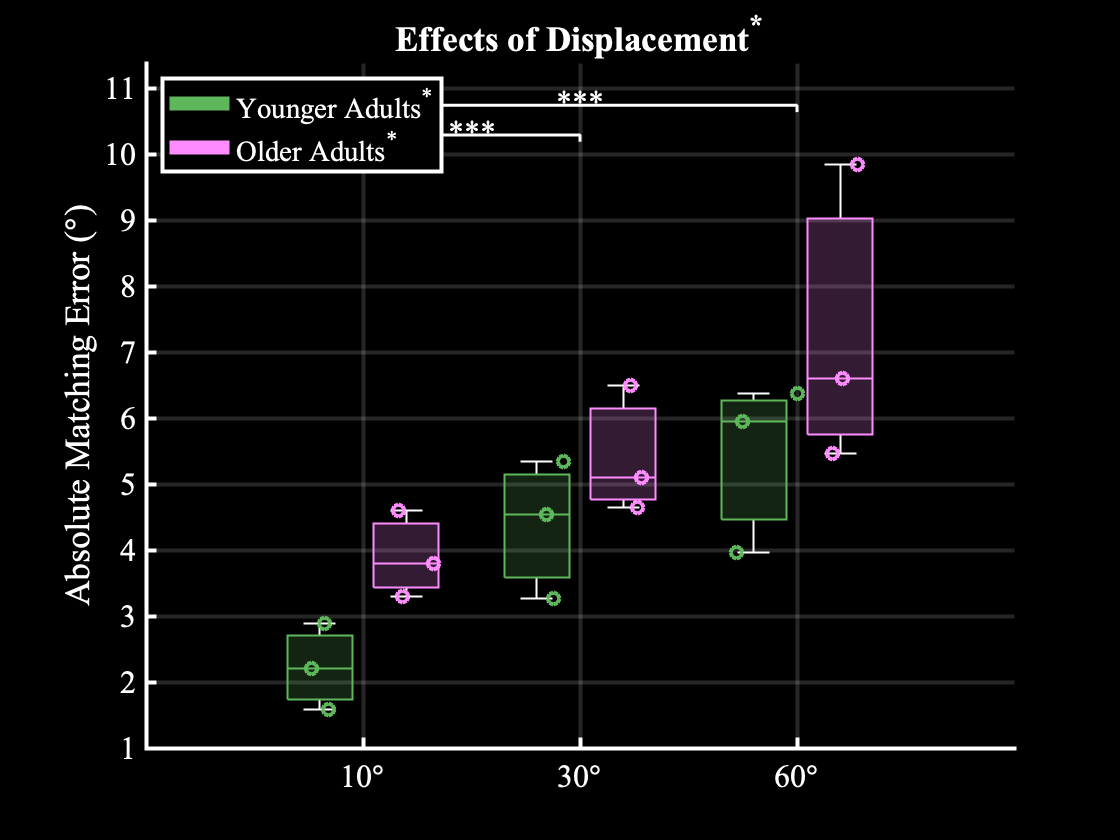

t1.effectsOfDisplacement(); 

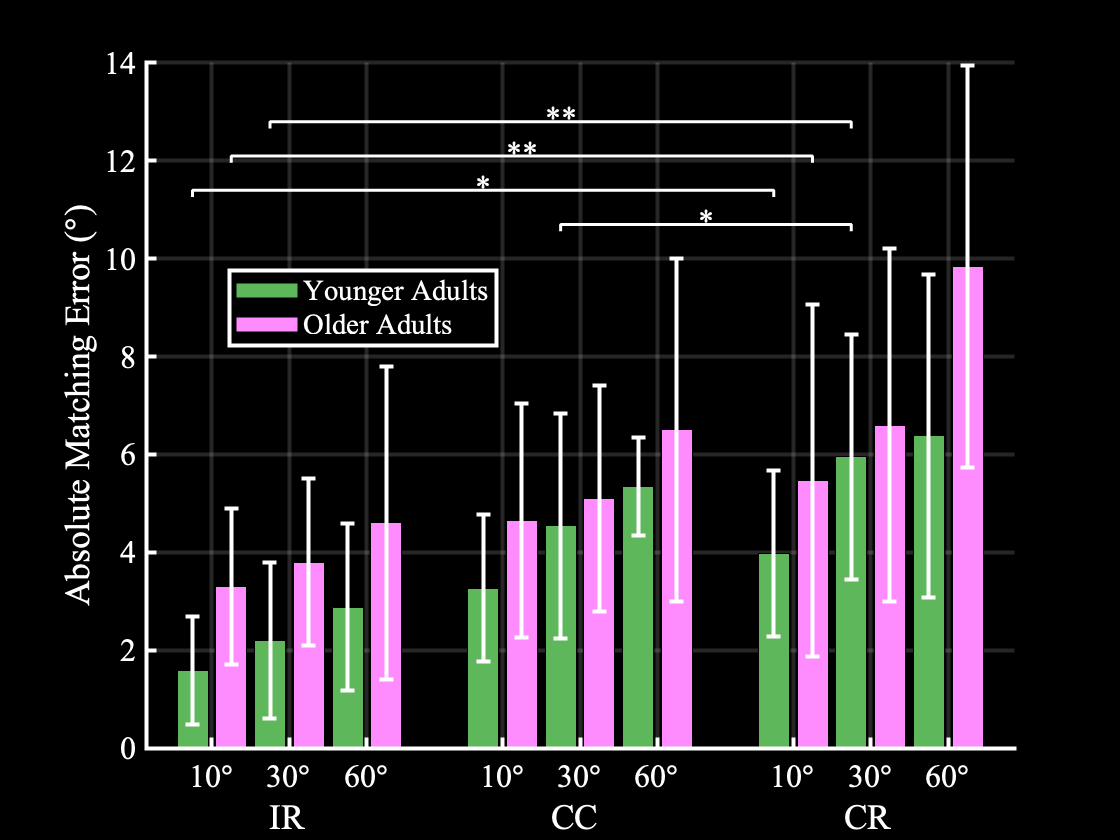

t1.basePlot({[1 1; 3 1], [1  2; 3 2], [1 3; 3 3], [2 3; 3 3]}, [0.03 0.007 0.002 0.02]);

## Table 2

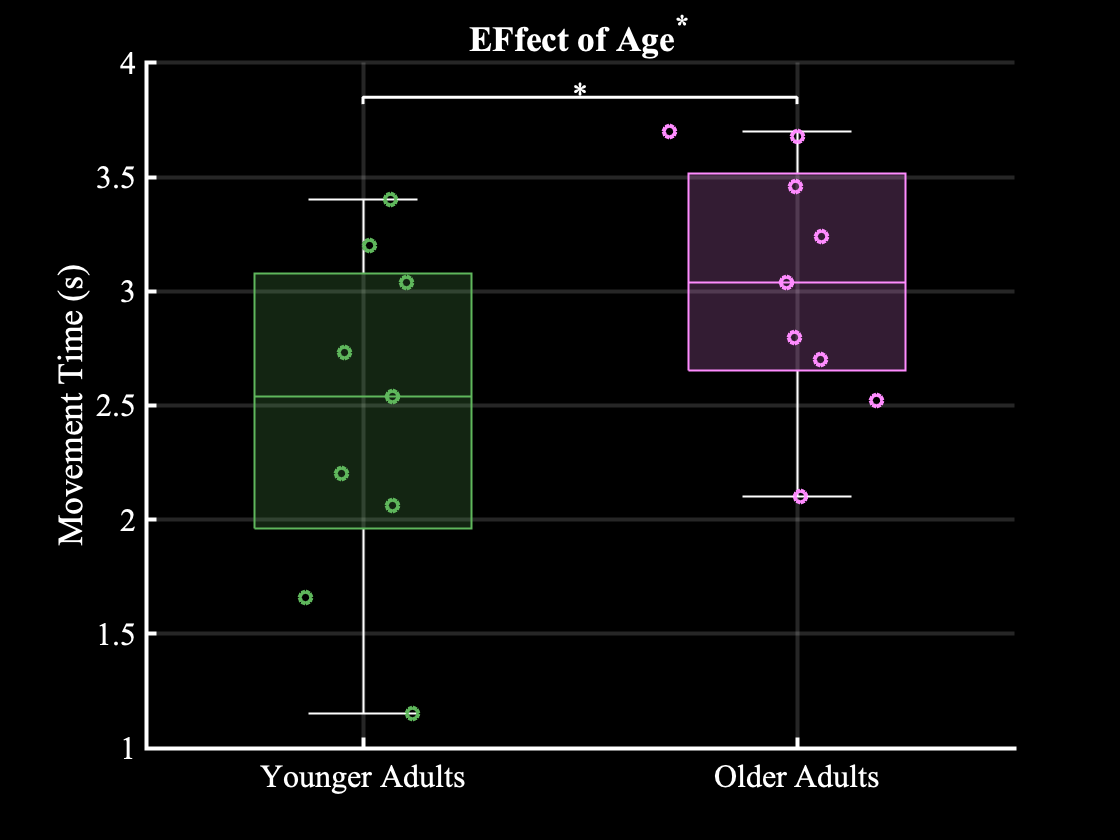

t2 = VisualizeAdamoTable(t2_YA, t2_OA, 'Movement Time (s)', 2);
% significance
set(t2, 'effectOfAge', true); set(t2, 'btwAge', 0.03);
set(t2, 'effectOfCondition', [false false false])
set(t2, 'effectOfDisplacement', [true true false]);
set(t2, 'btwDisplacements', [0.02 1 0.002]); set(t2, 'winDisplacements', [0.006 0.003 0.15]);
set(t2, 'btwConditions', [1 1 1]); set(t2, 'winConditions', [1 1 1]);
t2.effectsOfAge(); 

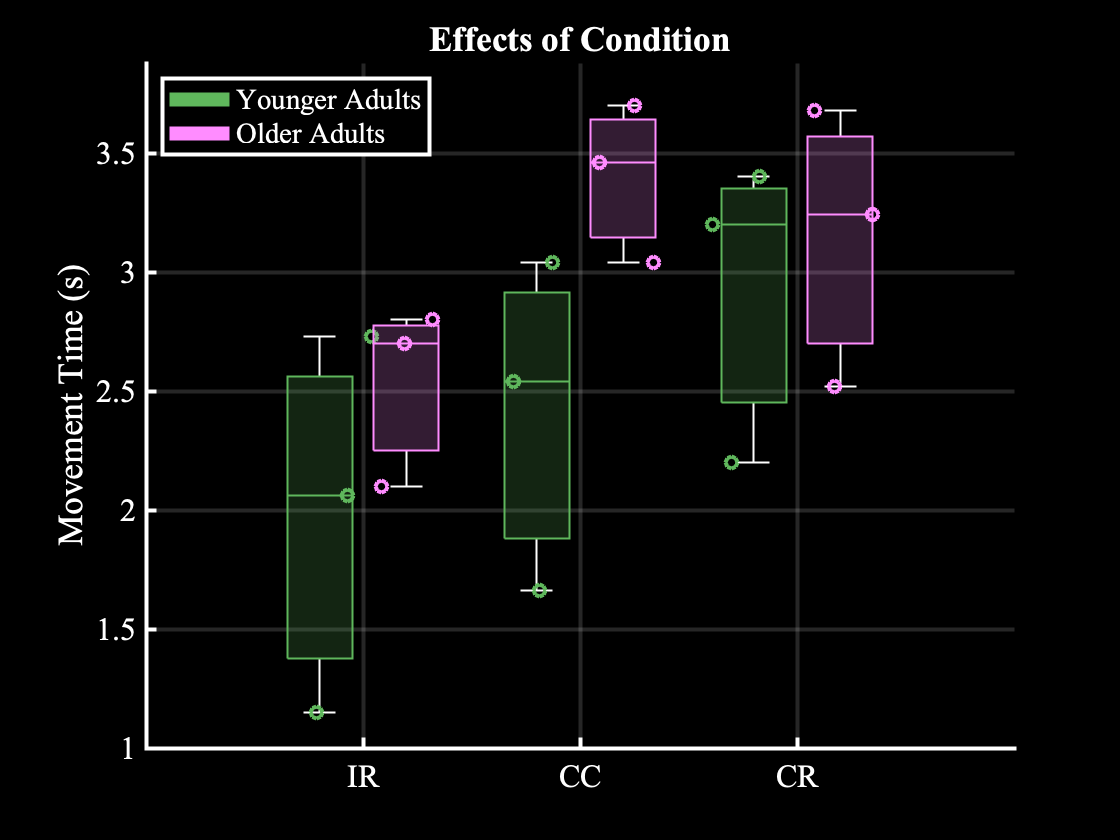

t2.effectsOfConditions();

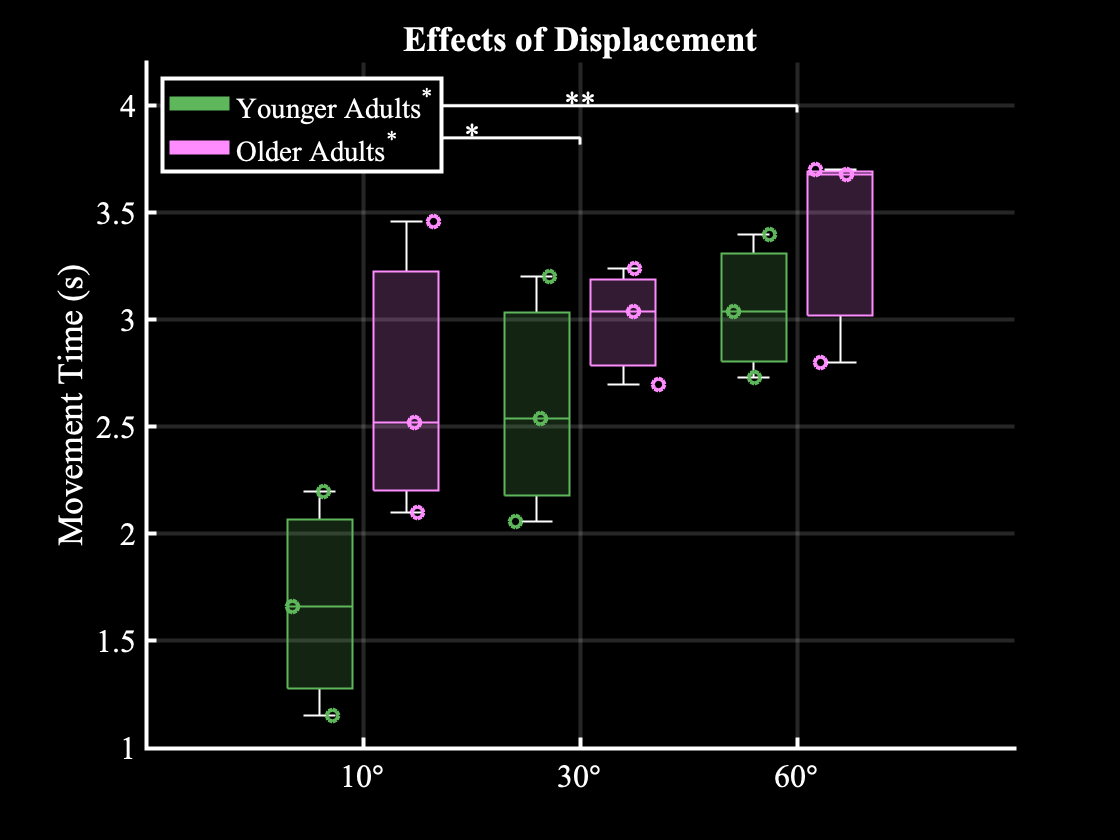

t2.effectsOfDisplacement(); 

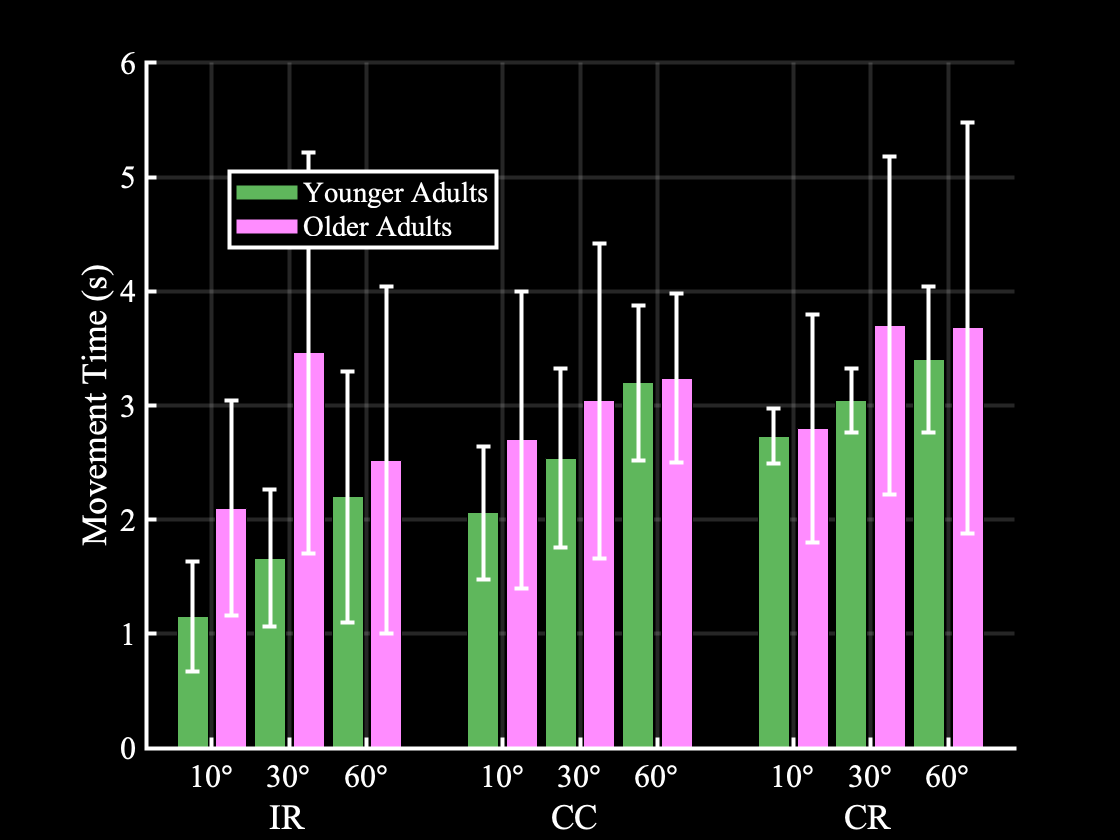

t2.basePlot({[1 1; 3 1]}, [1]);